%测试参数
Lena=imread("Lena256.bmp");
[M,N]=size(Lena);
[~,EncryptedMessage] = MyEncryptionAlgorithm(Lena);
c1=EncryptedMessage(1);
c2=EncryptedMessage(2);
c3=EncryptedMessage(3);
c4=EncryptedMessage(4);
m1=RSA(c1,"decrypt");
m2=RSA(c2,"decrypt");
m3=RSA(c3,"decrypt");
m4=RSA(c4,"decrypt");

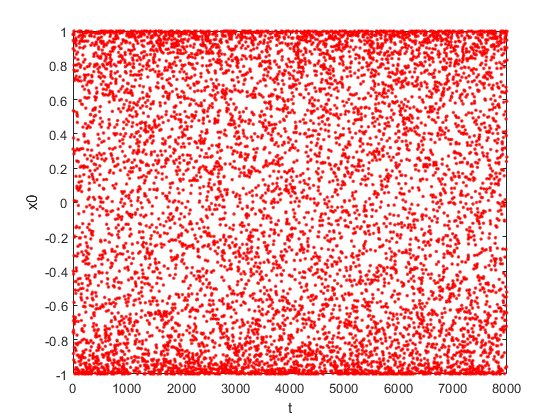


% 随机生成8000个x、y、z值
x = rand(8000,1);
y = rand(8000,1);
z = rand(8000,1);

% 调用函数fun1，并得到输出序列
[x_out,y_out,z_out] = fun1(x,y,z);


% 图1，显示变量x的输出序列
figure(1);
plot(x_out,"r.");

xlabel('t');
ylabel('x0');

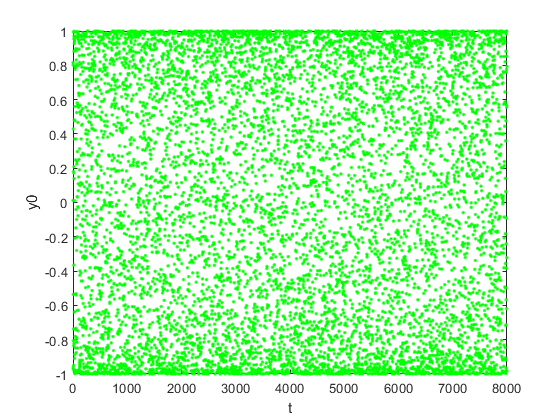


% 图2，显示变量y的输出序列
figure(2);
plot(y_out,"g.");

xlabel('t');
ylabel('y0');

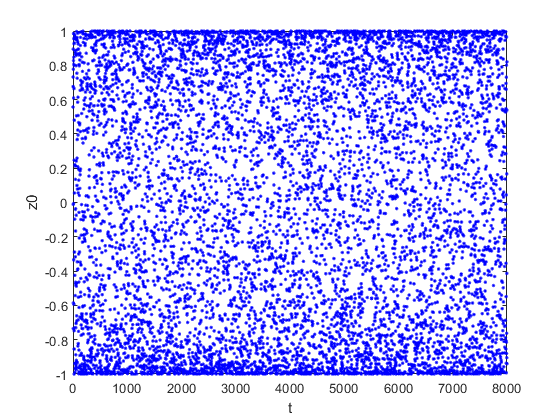


%子图3，显示变量z的输出序列
figure(3);
plot(z_out,"b.");

xlabel('t');
ylabel('z0');

function [x,y,z]=fun1(x0,y0,z0)
    m1=2090;m2=2412;m3=2151;m4=2088;
    c1=20311411;c2=39139570;c3=8451773;c4=11073535;
    M=256;N=256;
    x=sin((x0*M*N+c1/m1+log2(c4+m4))*pi/2);
    y=sin((y0*M*N+c2/m2+log2(c4+m4))*pi/2);
    z=sin((z0*M*N+c3/m3+log2(c4+m4))*pi/2);
end